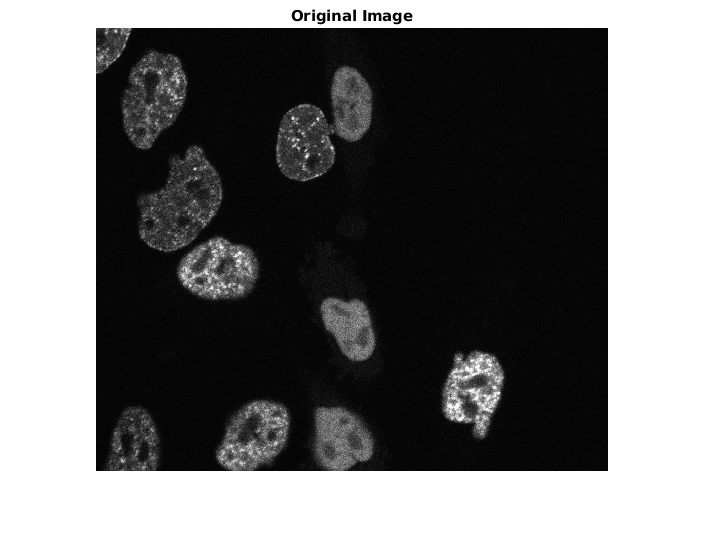

% Implementation of Phase Stretch Transform (PST) in Matlab
% Derived from work of: M. Asghari and Madhuri Suthar, Jalali Lab, Department of Electrical and Computer Engineering,  UCLA

clc  % clear screen
clear all  % clear all variables
close all   % close all figures
addpath('src/'); % script source directory

% New image loading
cell_dataset = cell_dataset('data/Fluo-N3DH-CHO/01/');
% implay(dataset(:,:,1,:), 4);

% Work with a single 3D image for now
Image_orig = cell_dataset(:,:,:,1);

% Repeat the Z axis by 5x, since the voxels are not even in X/Y/Z
% Voxel size (microns): 0.202 x 0.202 x 1.0
% Repeating Z axis by 5x should make the voxel size 0.202 x 0.202 x 0.2
% (good enough)
Image_orig = repelem(Image_orig, 1, 1, 5);

%show the original image
%subplot(1,2,1)
%Image_orig = im2double(Image_orig(:,:,:));
imshow(Image_orig(:,:,1))
title('Original Image') % convert the grayscale image do a 2D double array

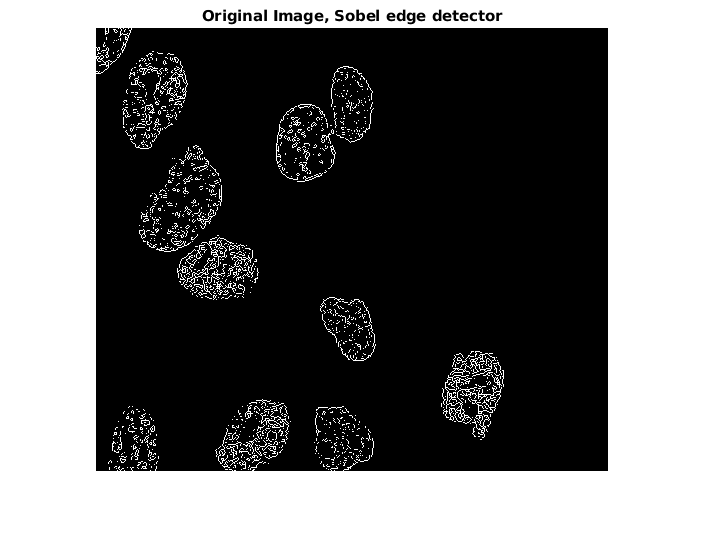

%Image_orig=double(Image_orig);

% MK: Show edges using 1st order Sobel edge detector kernel
figure;
edge(Image_orig(:,:,1), 'sobel');
title('Original Image, Sobel edge detector');

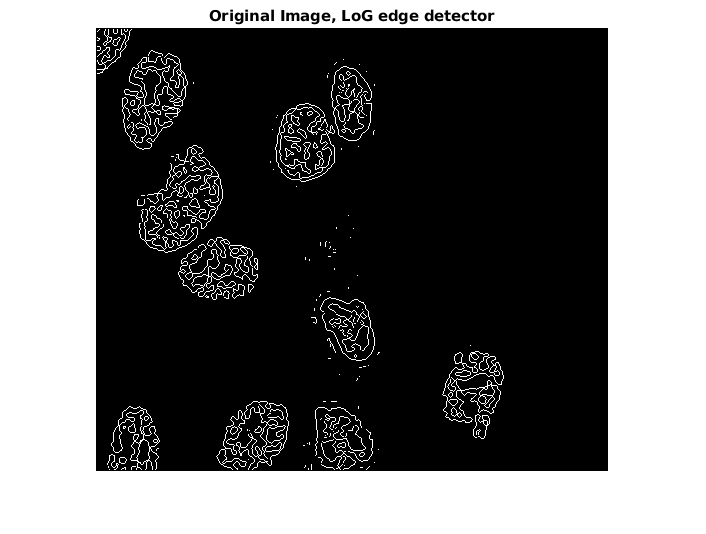

figure;
edge(Image_orig(:,:,1), 'log');
title('Original Image, LoG edge detector');

figure;

% low-pass filtering (also called localization) parameter
handles.LPF=0.2; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)

% PST parameters
handles.Phase_strength=0.48;  % PST  kernel Phase Strength
handles.Warp_strength=12.48;  % PST Kernel Warp Strength

% Thresholding parameters (for post processing)
handles.Thresh_min=-1;  % minimum Threshold  (a number between 0 and -1)
handles.Thresh_max= 0.0019;  % maximum Threshold  (a number between 0 and 1)
handles.Thresh_dark = 1/9; % dark threshold (between 0 and 1)

% Apply PST and find features (sharp transitions)
% [Edge, PST_Kernel]= PST(Image_orig,handles,Morph_flag);
[features, PST_Kernel] = PST_ND(Image_orig, handles);
[edge] = PST_post(Image_orig, features, handles);

%Attempt to find centroids of blobs
cc = bwconncomp(edge, 26);
stats = regionprops(cc, 'Centroid');
start_cents = [];
for i = 1:size(stats, 1)
    start_cents = [start_cents ; stats(i).Centroid];
end
prev_size = size(start_cents, 1);
true_centroids = centroid_reduction(start_cents, 50);
curr_size = size(true_centroids, 1);
while prev_size ~= curr_size
    true_centroids = centroid_reduction(true_centroids, 110);
    prev_size = curr_size;
    curr_size = size(true_centroids, 1);
end

% MK: Best edges on Z layer 21
refined_edge = edge(:,:,21:25);

% Show and save 'analog' edge output
filename = 't000.tif';
figure;
features_img = features(:,:,1)/max(features, [], 'all')*3

features_img =    -0.9841   -0.8949   -0.6514   -0.6073   -0.5617   -0.6220   -0.4727   -0.2183   -0.2731   -0.5657   -0.8620   -0.8564   -0.5941   -0.3457   -0.3438   -0.2233   -0.1638   -0.1038   -0.1780   -0.3544   -0.3625   -0.4052   -0.3720   -0.2152   -0.4498   -0.7368   -0.6719   -0.4579   -0.4098   -0.5102   -0.4823   -0.4947   -0.7444   -0.9357   -0.8594   -0.3664    0.1560    0.3319    0.3916    0.2040    0.0054    0.0515    0.2199    0.3044    0.4190    0.5063    0.4094    0.2427    0.3352    0.3191
   -0.9519   -0.9643   -0.7395   -0.6262   -0.4906   -0.5009   -0.4392   -0.2415   -0.2522   -0.5064   -0.7834   -0.7911   -0.5362   -0.2732   -0.1532   -0.0569   -0.1871   -0.3846   -0.5670   -0.6519   -0.5541   -0.4204   -0.2330   -0.0850   -0.2873   -0.5883   -0.6388   -0.5400   -0.5379   -0.4739   -0.3671   -0.4572   -0.7013   -0.8979   -0.9426   -0.5740    0.2281    0.9207    1.2387    1.3167    1.2384    1.1944    1.2797    1.3260    1.4559    1.5924    1.4409    1.0719    

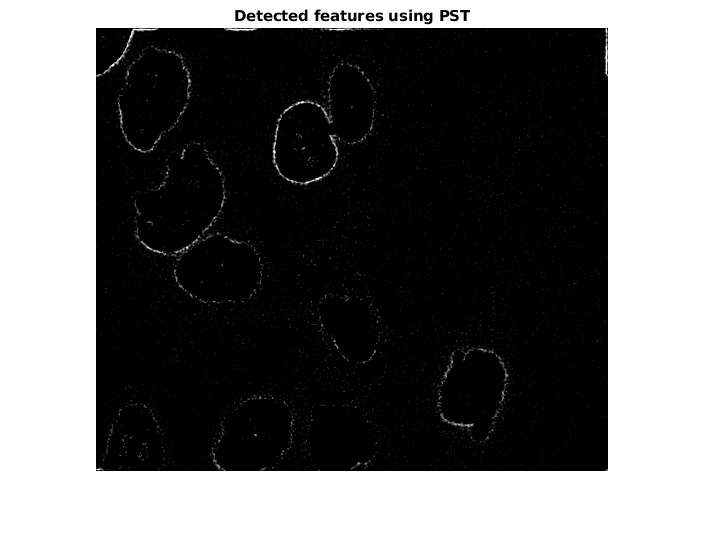

imshow(features_img)
title('Detected features using PST')

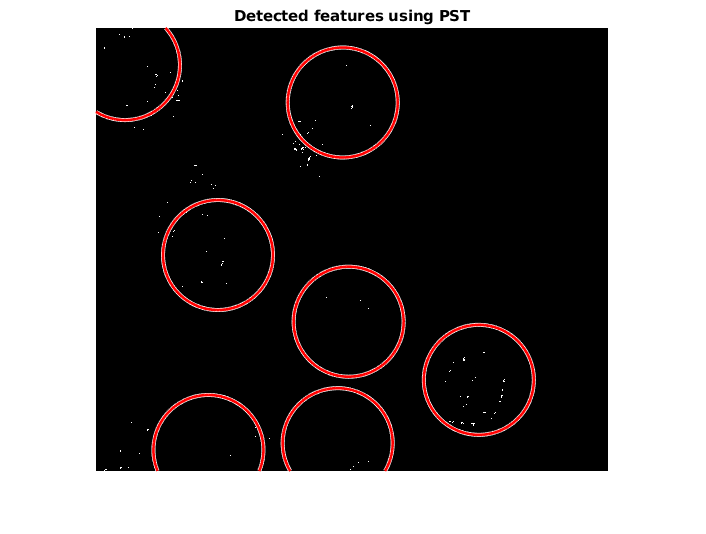

file_and_extension = strsplit(filename,'.');
output_path = char(strcat('data/Test_Images/',file_and_extension(1),'_features.tif'));
imwrite(features_img, output_path);

% Show and save thresholded edges
figure;
imshow(edge(:,:,1));
radii = ones(size(true_centroids, 1), 1) * 55;
viscircles(true_centroids(:,[1,2]), radii);
title('Detected features using PST')

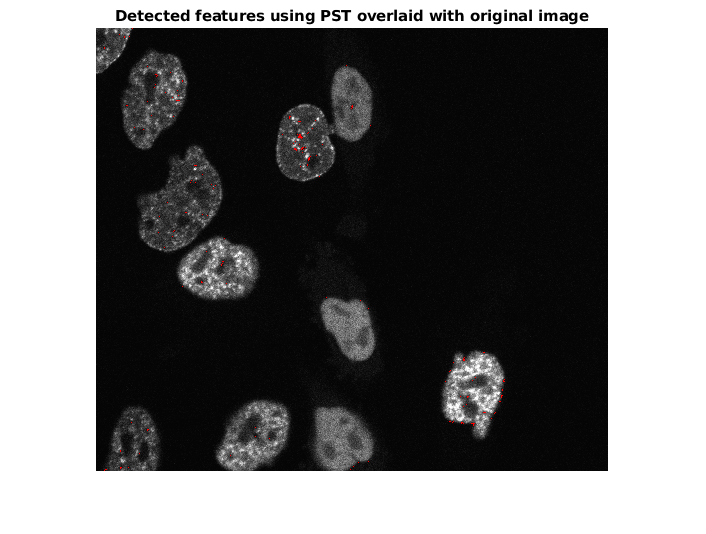

% save the image
file_and_extension=strsplit(filename,'.');
output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_edge.tif'));
imwrite(edge(:,:,1), output_path);
% overlay original image with detected features
overlay = double(imoverlay(Image_orig, edge(:,:,1)/1000000, [1 0 0]));
figure;
imshow(overlay/max(overlay, [], 'all'));
title('Detected features using PST overlaid with original image')

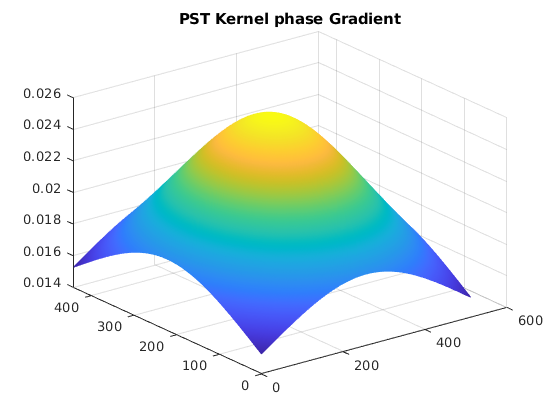

% save the image
output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_overlay.tif'));
imwrite(overlay/max(overlay, [], 'all'), output_path);

% show the PST phase kernel gradient
figure;
[D_PST_Kernel_x, D_PST_Kernel_y, D_PST_Kernel_z]=gradient(PST_Kernel);
mesh(sqrt(D_PST_Kernel_x(:,:,1).^2+D_PST_Kernel_y(:,:,1).^2+D_PST_Kernel_z(:,:,1).^2));
title('PST Kernel phase Gradient');